phi = 0;
W = 4;
D = 2;
L = 1;
rho_full = 1250;
rho_water = 1000;

disp_ratio = 0.25;
percent_infill = disp_ratio * (rho_water)/(rho_full);
f_rho_dynamic = @(y, h) ( (y >= h)*0.5*rho_full + (y < h)*rho_full );
f_rho_const = @(y, h) (percent_infill * rho_full);

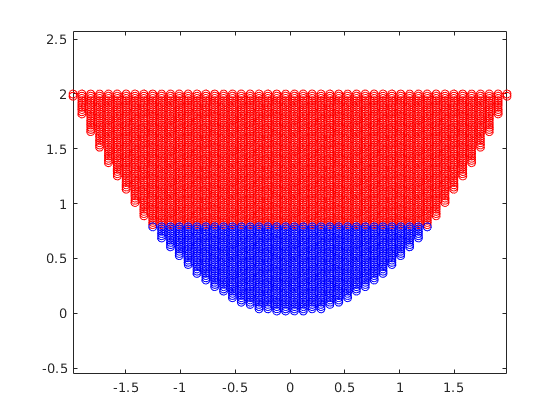

center_of_mass =     0.0000    1.2059


center_of_buoyancy =    -0.0000    0.4795


mass_boat = 1.3444e+03

mass_water = 1.3452e+03

f_contour_quadratic = @(x, y)(D * (2*x/W).^2 <= y);
[center_of_mass, center_of_buoyancy, mass_boat, mass_water] ...
    = boat_sim(phi, W, D, L, f_contour_quadratic, @(y) (f_rho_const(y, 0.2)), true)

f_contour_linear = @(x, y) (D * abs(2*x/W) <= y);

phis = 1:180;
moment_arms = zeros(size(phis));

for phi = phis
    moment_arms(phi) = moment_arm_func(phi, W, D, L, f_contour_linear, @(y)(f_rho_const(y, 0)));
end

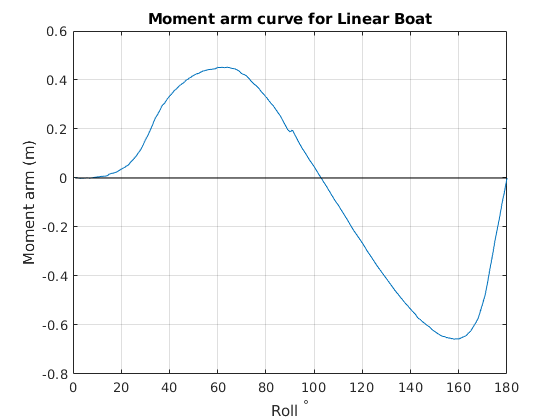

figure();
plot(phis, moment_arms);
line([min(phis), max(phis)], [0, 0], 'color', 'black')

grid on
title("Moment arm curve for Linear Boat")
xlabel("Roll ^\circ")
ylabel("Moment arm (m)")

avs = fzero(@(phi) (moment_arm_func(phi, W, D, L, f_contour_linear, @(y)(f_rho_const(y, 0))) ), [10 175]);
disp(avs)

  102.9606



calc_avs(W, D, L, f_contour_linear, @(y)(f_rho_const(y, 0)))

ans = 93

dividers_0 = [D/3, 2*D/3];
densities_0 = rho_full * [1, 0.5, 0.1];
x_0 = [W, D, dividers_0, densities_0];

f_cost = generate_cost_func(f_contour_quadratic)
tic
[min_params, max_avs] = fminsearch(@(params) (140 - calc_avs(params(1), params(2), L, f_contour_quadratic, generate_density_func(params(3:4), params(5:7)))), x_0 );
toc

% Simulate fminsearch found result
w_optim = min_params(1);
d_optim = min_params(2);
f_rho_optim = generate_density_func(min_params(3:4), min_params(5:7));
[avs, phis, moment_arms] = calc_avs(w_optim, d_optim, L, f_contour_quadratic, f_rho_optim);

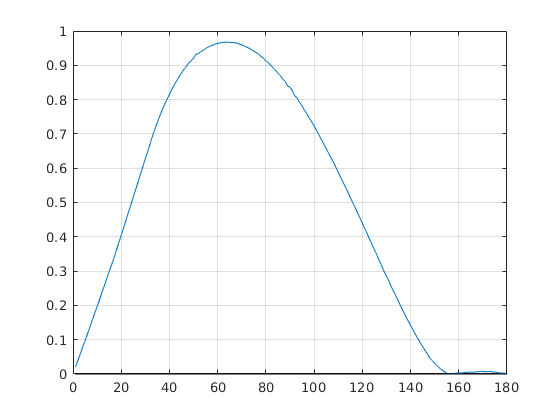

figure()
plot(phis, moment_arms);
line([min(phis), max(phis)], [0, 0], 'color', 'black')
grid on;

v_w = linspace(0.1, 8, 20);
v_d = linspace(0.1, 4, 20);
[mat_W, mat_D, mat_avs] = param_sweep(v_w, v_d, f_contour_quadratic, @(y)(f_rho_const(y, 0)));

i_max_avs = find(mat_avs == max(mat_avs, [], 'all'));

Unrecognized function or variable 'mat_avs'.

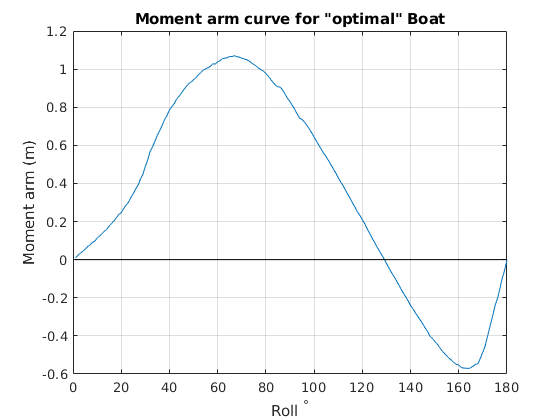

w_max = mat_W(i_max_avs);
d_max = mat_D(i_max_avs);
calc_avs(w_max, d_max, L, f_contour_quadratic, @(y) (f_rho_const(y, 0)))

phis = 10:170;
moment_arms = zeros(size(phis));

for phi = 1:length(phis)
    moment_arms(phi) = moment_arm_func(phi, w_max, d_max, L, f_contour_quadratic, @(y)(f_rho_const(y, 0)));
end

figure();
plot(phis, moment_arms);
line([min(phis), max(phis)], [0, 0], 'color', 'black')

grid on
title("Moment arm curve for ""optimal"" Boat")
xlabel("Roll ^\circ")
ylabel("Moment arm (m)")

function [mat_W, mat_D, mat_avs] = param_sweep(v_w, v_d, f_contour, f_rho)
    [mat_W, mat_D] = meshgrid(v_w, v_d);
    
    v_points = [mat_W(:), mat_D(:)];
    v_avs = zeros(length(v_points), 1);
    L = 1;
    for i = 1 : length(v_points)
        try
            v_avs(i) = calc_avs(v_points(i, 1), v_points(i, 2), L, f_contour, f_rho);
        catch exception
            % Check for the case of undefined AVS
            if strcmp(exception.identifier, 'MATLAB:fzero:ValuesAtEndPtsSameSign')
                fprintf("AVS undefined at [w, d] = [%f, %f]\n", v_points(i, 1), v_points(i, 2));
                v_avs(i) = 0;
            else
                % Otherwise throw error
                fprintf("Error at params [%f, %f]", v_points(i, 1), v_points(i, 2));
                throw(exception)
            end            
            
        end
    end
    mat_avs = reshape(v_avs, size(mat_W));
end

function [f_rho] = generate_density_func(dividers, densities)
    densities = abs(densities);
    f_rho = @(y)( (y <= dividers(1))*densities(1) + ...
            (y > dividers(1) & y <= dividers(2))*densities(2) + ...
            (y > dividers(2))*densities(3) );
end

function f_cost = generate_cost_func(f_contour)
    L = 1;
    f_cost = @(params) (140 - calc_avs(params(1), params(2), L, f_contour, generate_density_func(params(3:4), params(5:7))));

end